# Assignment 3 – Case Study

MAP55672 | Author: [Your Name]

DEPENDENCIES cg_solve.m (included in this submission) get_covariance_matrix.m (provided on Blackboard)

clear; clc; close all;

Signature: [x, rel_res_history, num_iter] = cg_solve(A, b, tol, max_iter)

Algorithm follows Saad, "Iterative Methods for Sparse Linear Systems", 2nd ed., Algorithm 6.18.

fprintf('=== Question 1: CG algorithm is in cg_solve.m ===\n\n');

=== Question 1: CG algorithm is in cg_solve.m ===



tol      = 1e-8;
max_iter = 5000;
tau      = 20;
noise    = 0.005;
sizes    = [256, 512, 1024];   % three dimensions of A

fprintf('=== Question 2 ===\n');

=== Question 2 ===


fprintf('tau = %g,  noise = %g,  tol = %.0e\n\n', tau, noise, tol);

tau = 20,  noise = 0.005,  tol = 1e-08



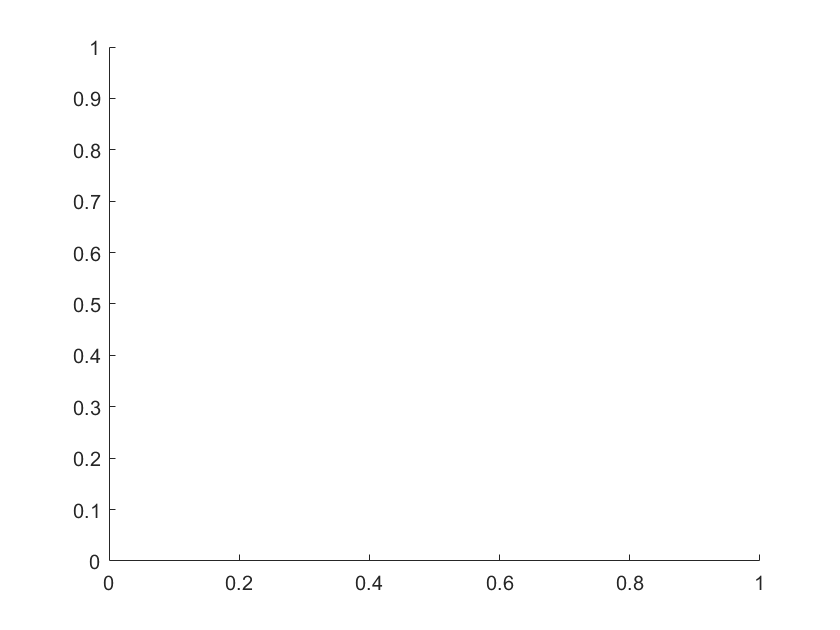


results_q2 = struct();

figure('Name', 'Q2 – CG Convergence (three sizes)');
hold on;


colors = {'#0072BD', '#D95319', '#77AC30'};

for i = 1 : numel(sizes)
    N = sizes(i);
    [A, b] = get_covariance_matrix(N, tau, noise);

    [x, rel_res, num_iter] = cg_solve(A, b, tol, max_iter);

    % Store results
    results_q2(i).N        = N;
    results_q2(i).x        = x;
    results_q2(i).num_iter = num_iter;
    results_q2(i).rel_res  = rel_res;

    fprintf('N = %4d  →  iterations: %4d,  final rel. res: %.2e\n', ...
            N, num_iter, rel_res(end));

    semilogy(1:num_iter, rel_res, 'Color', colors{i}, 'LineWidth', 1.5, ...
             'DisplayName', sprintf('N = %d', N));
end

函数或变量 'get_covariance_matrix' 无法识别。


yline(tol, 'k--', 'LineWidth', 1, 'DisplayName', 'Tolerance 10^{-8}');
xlabel('Iteration');
ylabel('Relative residual $\|r_k\| / \|r_0\|$', 'Interpreter', 'latex');
title('Q2 – CG Convergence for Three Matrix Sizes  (\tau=20, noise=0.005)');
legend('Location', 'northeast');
grid on;
hold off;

fprintf('\n');

tau_q3 = 393;   

noise_values = logspace(log10(0.5), log10(0.5e-8), 20);  % 20 points from 0.5 to 0.5e-8
N_q3         = 512;   % fixed matrix size for this test

fprintf('=== Question 3 ===\n');
fprintf('tau = %g,  N = %d\n', tau_q3, N_q3);
fprintf('%-15s  %-10s  %-12s\n', 'Noise', 'Iterations', 'Cond(A)');

iter_q3  = zeros(numel(noise_values), 1);
cond_q3  = zeros(numel(noise_values), 1);

for i = 1 : numel(noise_values)
    nv        = noise_values(i);
    [A, b]    = get_covariance_matrix(N_q3, tau_q3, nv);
    cond_q3(i) = cond(A);
    [~, ~, num_iter] = cg_solve(A, b, tol, max_iter);
    iter_q3(i) = num_iter;
    fprintf('%.4e      %-10d  %-12.2e\n', nv, num_iter, cond_q3(i));
end

% --- Plot: noise vs iterations ---
figure('Name', 'Q3 – Noise vs Iterations');
semilogx(noise_values, iter_q3, 'o-', 'LineWidth', 1.5, 'Color', '#0072BD', ...
         'MarkerFaceColor', '#0072BD');
set(gca, 'XDir', 'reverse');   % decreasing noise left-to-right
xlabel('Noise level');
ylabel('Number of CG iterations');
title(sprintf('Q3 – CG Iterations vs Noise Level  (\\tau=%d, N=%d)', tau_q3, N_q3));
grid on;

% --- Plot: noise vs condition number ---
figure('Name', 'Q3 – Noise vs Condition Number');
loglog(noise_values, cond_q3, 's-', 'LineWidth', 1.5, 'Color', '#D95319', ...
       'MarkerFaceColor', '#D95319');
set(gca, 'XDir', 'reverse');
xlabel('Noise level');
ylabel('Condition number  \kappa(A)');
title(sprintf('Q3 – Condition Number vs Noise Level  (\\tau=%d, N=%d)', tau_q3, N_q3));
grid on;

% --- Plot: condition number vs iterations (direct relationship) ---
figure('Name', 'Q3 – Condition Number vs Iterations');
loglog(cond_q3, iter_q3, 'o', 'LineWidth', 1.5, 'Color', '#77AC30', ...
       'MarkerFaceColor', '#77AC30');
xlabel('Condition number  \kappa(A)');
ylabel('Number of CG iterations');
title('Q3 – CG Iterations vs Condition Number');
grid on;

fprintf('\n');

fprintf('=== Question 4 ===\n');

[A_q4, b_q4] = get_covariance_matrix(1024, 100, 0.05);

% --- Run CG on original A ---
[x_orig, rel_res_orig, iter_orig] = cg_solve(A_q4, b_q4, tol, max_iter);
fprintf('Original A:       iterations = %d,  final rel. res = %.2e\n', ...
        iter_orig, rel_res_orig(end));

% --- Build preconditioned system ---
% M = chol(A)  =>  A = M' * M  (upper triangular Cholesky factor)
% A_new = M \ (A / M')  =  M^{-1} * A * M^{-T}
% This transforms A into a matrix that is similar to the identity when
% A is well-conditioned, clustering the eigenvalues around 1.
M     = chol(A_q4);
A_new = M \ (A_q4 / M');

% A_new may have tiny asymmetric floating-point errors; symmetrize
A_new = (A_new + A_new') / 2;

% b must also be transformed: b_new = M \ b  (so M^{-T} M^{-1} A M^{-T} y = M^{-T}b,
% but here we simply use b_new = M \ b for the transformed system)
b_new = M \ b_q4;

[x_new_transformed, rel_res_new, iter_new] = cg_solve(A_new, b_new, tol, max_iter);
fprintf('Preconditioned A: iterations = %d,  final rel. res = %.2e\n', ...
        iter_new, rel_res_new(end));

% Recover original solution from transformed one
% x_orig ≈ M' \ x_new_transformed
x_recovered = M' \ x_new_transformed;
fprintf('Solution recovery error: ||x_orig - x_recovered|| / ||x_orig|| = %.2e\n\n', ...
        norm(x_orig - x_recovered) / norm(x_orig));

% --- Condition numbers ---
kappa_orig = cond(A_q4);
kappa_new  = cond(A_new);
fprintf('kappa(A)     = %.4e\n', kappa_orig);
fprintf('kappa(A_new) = %.4e\n\n', kappa_new);

% --- Eigenvalue comparison ---
% (Only feasible for moderate N; for N=1024 this is slow but instructive)
fprintf('Computing eigenvalues (this may take a moment for N=1024)...\n');
eigs_orig = sort(eig(A_q4),  'ascend');
eigs_new  = sort(eig(A_new), 'ascend');
fprintf('Done.\n\n');

figure('Name', 'Q4 – Eigenvalue Comparison');
subplot(1,2,1);
plot(eigs_orig, 'o', 'MarkerSize', 3, 'Color', '#0072BD');
xlabel('Index');  ylabel('\lambda');
title('Eigenvalues of A');  grid on;

subplot(1,2,2);
plot(eigs_new, 'o', 'MarkerSize', 3, 'Color', '#D95319');
xlabel('Index');  ylabel('\lambda');
title('Eigenvalues of A_{new}');  grid on;

sgtitle('Q4 – Eigenvalue Spectra Before and After Cholesky Transformation');

% --- Convergence comparison ---
figure('Name', 'Q4 – CG Convergence Comparison');
hold on;
semilogy(1:iter_orig, rel_res_orig, 'LineWidth', 1.5, 'Color', '#0072BD', ...
         'DisplayName', 'Original A');
semilogy(1:iter_new,  rel_res_new,  'LineWidth', 1.5, 'Color', '#D95319', ...
         'DisplayName', 'Preconditioned A_{new}');
yline(tol, 'k--', 'LineWidth', 1, 'DisplayName', 'Tolerance 10^{-8}');
xlabel('Iteration');
ylabel('Relative residual $\|r_k\| / \|r_0\|$', 'Interpreter', 'latex');
title('Q4 – CG Convergence: Original vs Cholesky-Preconditioned');
legend('Location', 'northeast');
grid on;
hold off;

fprintf('=== All questions complete ===\n');